clear;clc;close all;
L = 200;
j = 1;
kT = 0.5;
n = L^2/10;
sigma = 0.1;
t_max = 600;
mode = 1;
[spin, X, Y] = XYInitialization(L);
vort = XYVorticity(spin,L);
div = XYDivergence(X, Y, L);
%outputVideo = VideoWriter('XY_Metropolis_animation_spin.avi', 'Uncompressed AVI');
outputVideo = VideoWriter('XY_Metropolis_animation_div.avi', 'Motion JPEG AVI');
%outputVideo = VideoWriter('XY_Metropolis_animation_vort.avi', 'Uncompressed AVI');
outputVideo.FrameRate=10

outputVideo =   VideoWriter

    General Properties:

       Filename:                 'XY_Metropolis_animation_div.avi'
       Path:                     '/MATLAB Drive/PHYS 416'
       FileFormat:               'avi'
       Duration:                 0

    Video Properties:

       ColorChannels:            3
       Height:                   []
       Width:                    []
       FrameCount:               0
       FrameRate:                10
       VideoBitsPerPixel:        24
       VideoFormat:              'RGB24'
       VideoCompressionMethod:   'Motion JPEG'
       Quality:                  75

  Methods


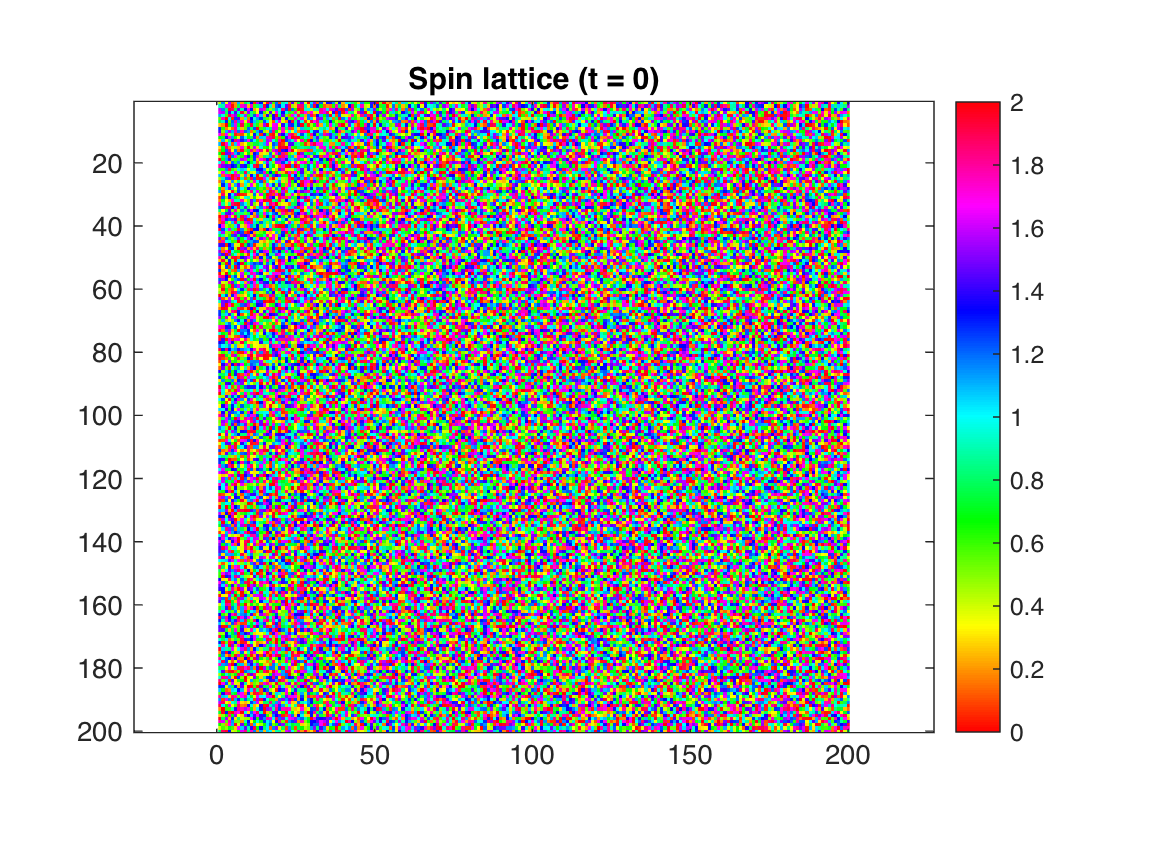

open(outputVideo);

figure(1)
imagesc(spin);
%imagesc(div);
%imagesc(vort);
axis equal
colormap('hsv')
colorbar
clim([0,2])
%title("Vorticity (t = 0)")
%clim([-2.9,2.9])
%title("Divergence (t = 0)")
title("Spin lattice (t = 0)")
frame = getframe(gcf);

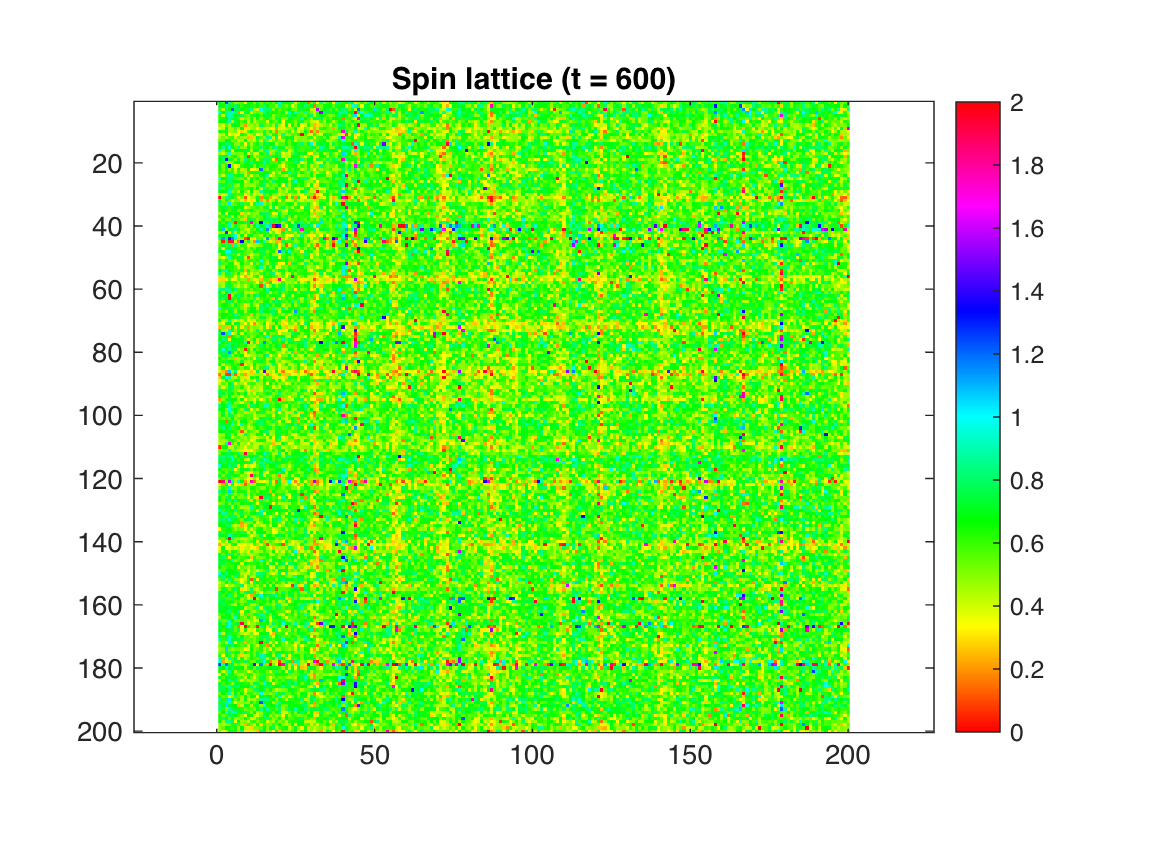


for t = 1:t_max
    [spin, X, Y] = XYMetropolis(spin, kT, j, L, n, sigma, mode);
    vort = XYVorticity(spin, L);
    div = XYDivergence(X, Y, L);
    imagesc(spin);
    %imagesc(div);
    %imagesc(vort);
    axis equal
    colormap('hsv')
    colorbar
    clim([0,2])
    title(sprintf("Spin lattice (t = %d)", t))
    %clim([-2.9,2.9])
    %title(sprintf("Divergence (t = %d)", t))
    %title(sprintf("Vorticity (t = %d)", t))
    frame = getframe(gcf);
    writeVideo(outputVideo, frame);
end